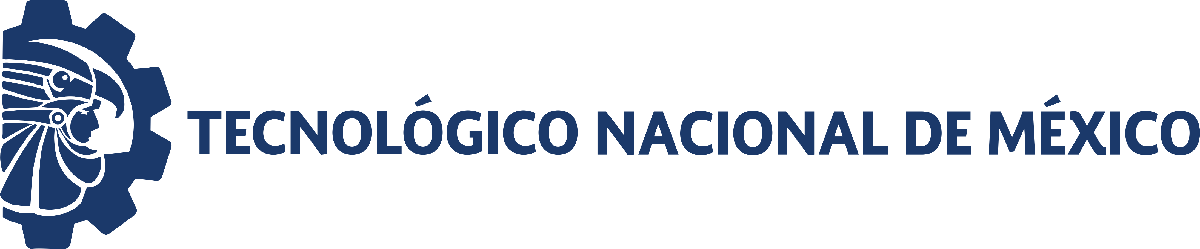                                 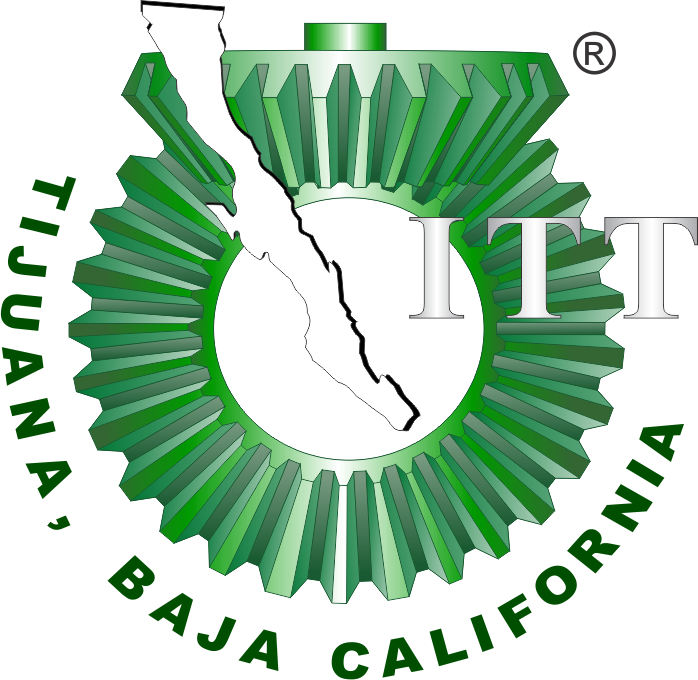

# Práctica 3: Sistema Musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

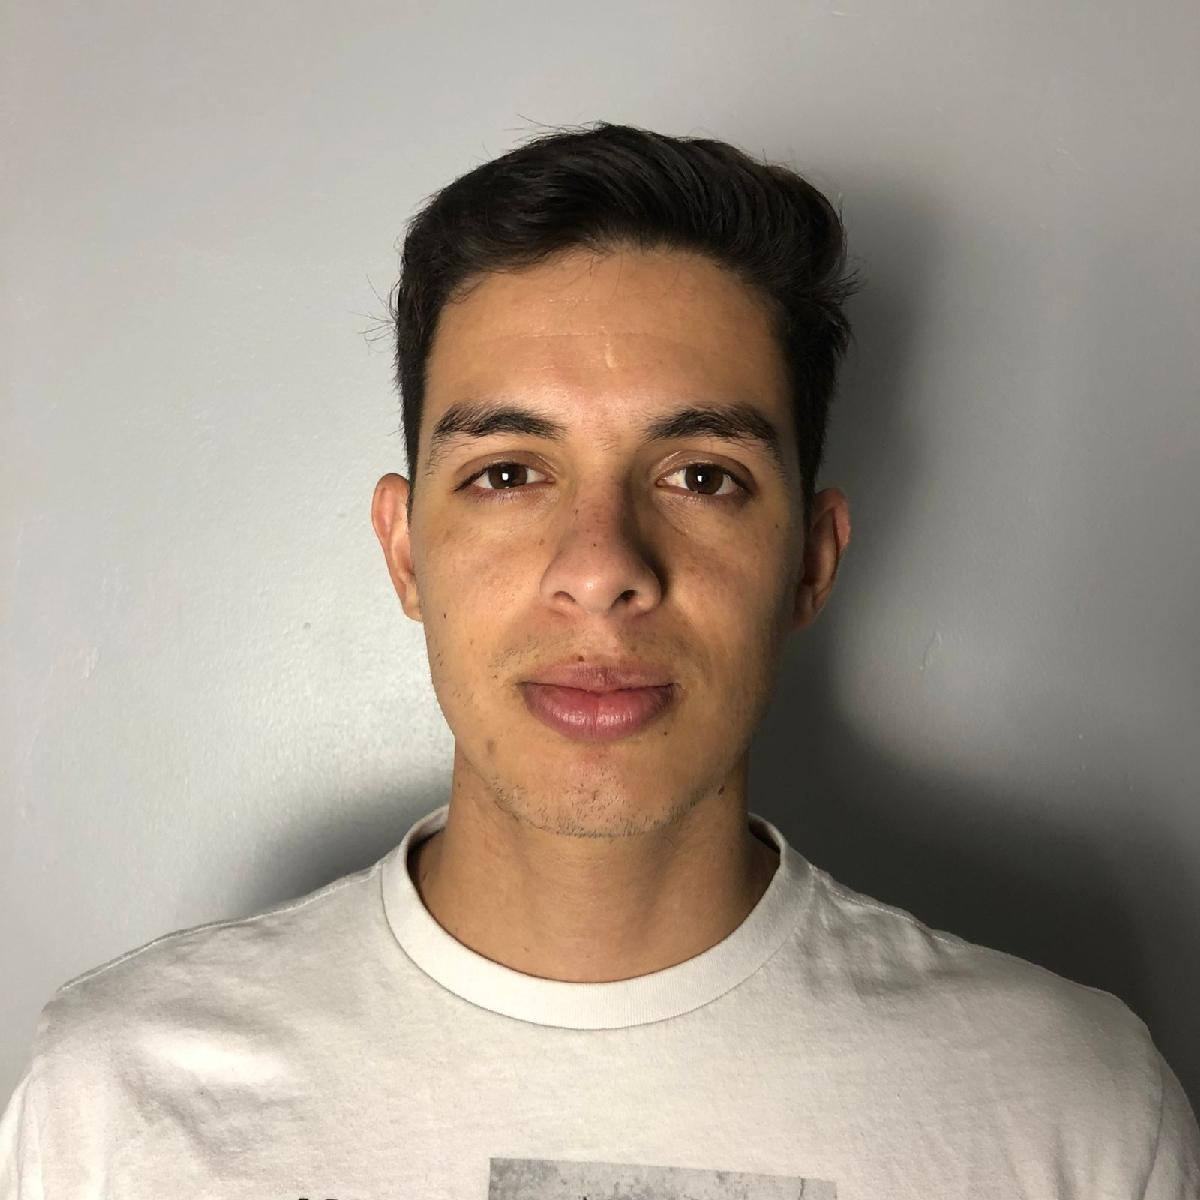

Nombre del alumno: Chizek Espinoza Josue

Número de control: 22212382

Correo institucional: l22212382**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulacion

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaD';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
set_param('SistemaD/F(t)','Amplitude','1');
set_param('SistemaD/F(t)','Period','10');
set_param('SistemaD/F(t)','PulseWidth','10');
set_param('SistemaD/F(t)','PhaseDelay','1');

## Respuesta de la señal musculoesqueletico en lazo abierto

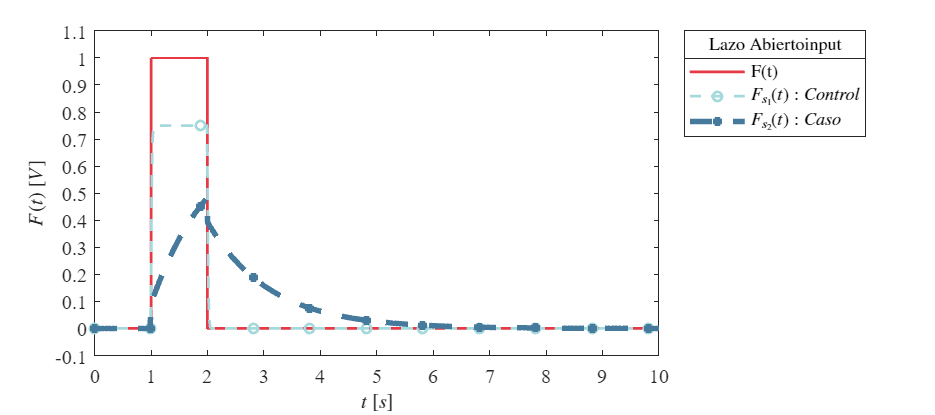

Signal = 'Lazo Abierto';
X = sim(file,parameters);
plotsignals2(X.t,X.F,X.Fs1,X.Fs2,Signal)

## Respuesta de la señal musculoesqueletico en lazo cerrado

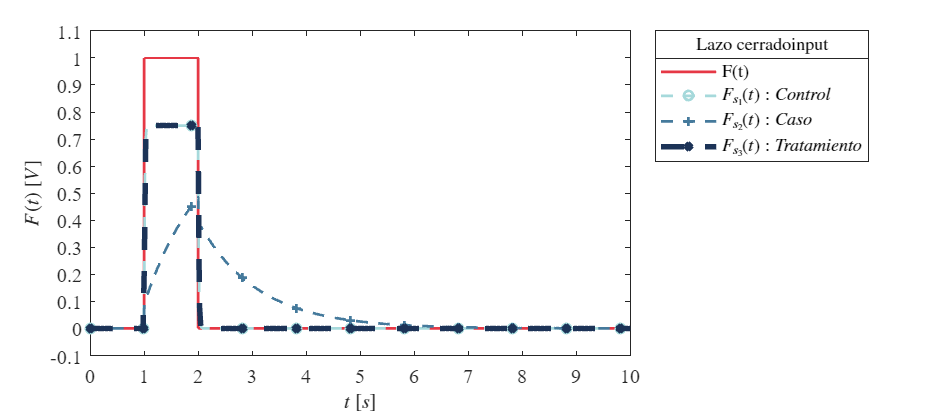

Signal='Lazo cerrado';
X1 = sim(file,parameters);
plotsignals(X1.t,X1.F,X1.Fs1,X1.Fs2,X1.Fs3,Signal)

## Función: Respuesta a las señáles

function plotsignals(t,F,Fs1,Fs2,Fs3,Signal)
    set(figure(),'Color','w')
    set(gcf, 'units','centimeters', 'position', [1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on;grid off;box on;
    mycolors = [0.90,0.22,0.27;
                0.65,0.85,0.86;
                0.27,0.48,0.61;
                0.11,0.20,0.34;
                0.13,0.34,0.31;
                0.56,0.39,0.23];
    colororder(mycolors)
    
 
 p=plot(t, F, '-', t, Fs1, '--o',t,Fs2, '--+',t,Fs3,'--x', ...
       'LineWidth', 1.5,'MarkerSize',5, 'MarkerIndices',1:1000:length(t));
  set(p(4),'LineWidth',3);
   L = legend('F(t)', '$F_{s_1}(t): Control$', '$F_{s_2}(t): Caso $', '$F_{s_3}(t): Tratamiento$');
   set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
   title (L, [Signal, 'input'], 'FontSize',10)


    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$F(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    if Signal =="Lazo cerrado"
        xlim([0,10]); xticks(0:1:10);
        ylim([-0.1,1.1]); yticks (-0.1:0.1:10)
    end

end


function plotsignals2(t,F,Fs1,Fs2,Signal)
   set(figure(), 'Color', 'w')
   set(gcf, 'units', 'centimeters', 'position', [1,1,18,8] )
   set(gca, 'FontName', 'Times New Roman', 'FontSize',11)
   hold on; grid off; box on;
   mycolors = [0.90,0.22,0.27;
                0.65,0.85,0.86;
                0.27,0.48,0.61;
                0.11,0.20,0.34;
                0.13,0.34,0.31;
                0.56,0.39,0.23];
   colororder(mycolors)

   p=plot(t, F, '-', t, Fs1, '--o',t,Fs2, '--+', ...
       'LineWidth', 1.5,'MarkerSize',5, 'MarkerIndices',1:1000:length(t));
  set(p(3),'LineWidth',3);
   L = legend('F(t)', '$F_{s_1}(t): Control$', '$F_{s_2}(t): Caso$');
   set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
   title (L, [Signal, 'input'], 'FontSize',10)


   xlabel('$t$ $[s]$', 'Interpreter','Latex', 'FontSize',11)
   ylabel('$F(t)$ $[V]$', 'Interpreter','Latex', 'FontSize',11)

   if Signal =="Lazo Abierto"
        xlim([0,10]); xticks(0:1:10);
        ylim([-0.1,1.1]); yticks (-0.1:0.1:10)
    end



end